# Plotter

Ce fichier .mlx permet de plotter les données obtenues lors des essais

## Trajectoires

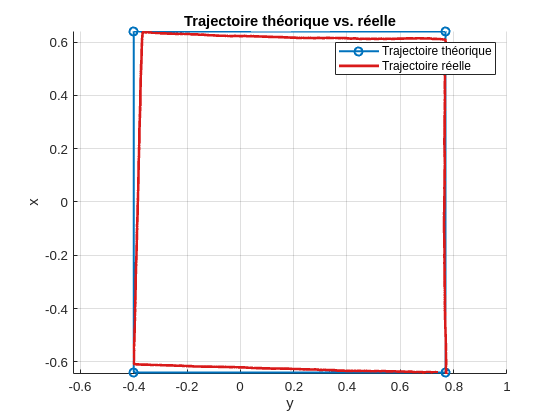

clear all

% === Tracé ===
figure;
hold on;
grid on;
axis equal;

% Lire les lignes du fichier
filename = '~/mecanum/csv/barycenter_logger.csv';
lines = readlines(filename);

% Extraire le type de trajectoire depuis la première ligne
trajectory_type_line = lines(1);
trajectory_type = strtrim(extractAfter(trajectory_type_line, 'trajectory_type:'));

% Lire les données de trajectoire (en ignorant les 2 premières lignes)
data = readtable(filename, 'NumHeaderLines', 2);

if strcmpi(trajectory_type, 'eight')
    % === Trajectoire théorique ===
    a = 1.0;
    b = 0.23;
    num_points = 16;
    start_x = -0.64;
    start_y = -0.77;
    
    X = zeros(num_points + 2, 1);
    Y = zeros(num_points + 2, 1);
    
    X(1) = start_x;
    Y(1) = start_y;
    
    for i = 1:num_points-1
        t = 2 * pi * (i-1) / num_points;
        X(i+1) = a * sin(t);
        Y(i+1) = b * sin(2 * t);
    end
    
    X(end) = start_x;
    Y(end) = start_y;
    % Trajectoire théorique (points cibles)
    plot(-Y, X, '-o', 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Trajectoire théorique');
    % Numérotation des points
    for i = 1:length(X)
        text(-Y(i)+0.01, X(i)+0.01, num2str(i-1), 'FontSize', 8);
    end
    hold on
elseif strcmpi(trajectory_type, 'rectangle')
    vertices = [
        -0.64, -0.77;
         0.64, -0.77;
         0.64,  0.4;
        -0.64,  0.4;
        -0.64, -0.77;
    ];
    plot(-vertices(:,2), vertices(:,1), '-o', 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Trajectoire théorique');
    hold on
end

% === Trajectoire réelle depuis CSV ===
data = readtable("~/mecanum/csv/barycenter_logger.csv");

% Extraire x et y
x_real = data.x;
y_real = data.y;

% Trajectoire réelle (essaim)
plot(-y_real, x_real, '-', 'Color', [0.85 0.1 0.1], 'LineWidth', 2, 'DisplayName', 'Trajectoire réelle');

xlabel('y');
ylabel('x');
title('Trajectoire théorique vs. réelle');
legend;

## Distances

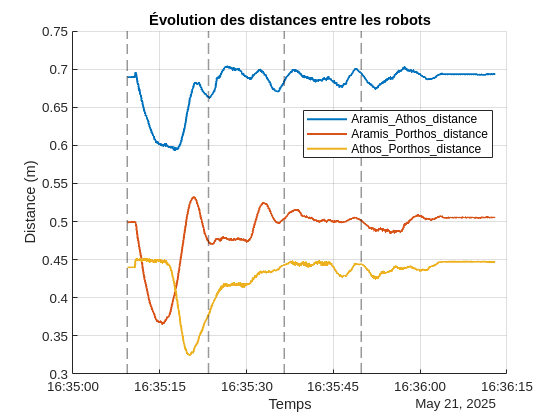

warning('off', 'all');

% === Paramètres ===
fichier_distance = '~/mecanum/csv/distance_logger.csv';   % CSV des distances
fichier_trajectoire = '~/mecanum/csv/goal_point_logger.csv';    % CSV des timestamps de position

% === Lecture du fichier des distances ===
data = readtable(fichier_distance);
timestamps = datetime(data{:, 1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');

% === Lecture du fichier de trajectoire ===
trajectoire = readtable(fichier_trajectoire);
timestamps_points = datetime(trajectoire{:, 1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');

% === Tracé des distances ===
figure;
hold on;
grid on;

% Tracer chaque courbe de distance
for i = 2:width(data)
    nom_distance = data.Properties.VariableNames{i};
    valeurs = data{:, i};
    
    plot(timestamps, valeurs, 'DisplayName', strrep(nom_distance, '_', '\_'), 'LineWidth', 1.5);
end

% === Ajout des lignes verticales pour chaque point de trajectoire ===
yl = ylim;  % Limites verticales du graphe
for i = 2:length(timestamps_points)
    xline(timestamps_points(i), 'k--', 'LineWidth', 1.2, 'Alpha', 0.4, 'HandleVisibility', 'off');
end

xlabel('Temps');
ylabel('Distance (m)');
title('Évolution des distances entre les robots');
legend('Location', 'best');